# Simulation of different cases

## General case example:

### Orbit, Time and Attitude parameters

In this section of the code, the following parameters are set: Orbit (with the 6 orbital parameters, RAAN defines the beta angle), the date of the simulation and what is the pointing of the satellite. the pointing mode can be set as:

- MODE = 1: "orbital" Reference quaternion is aligned with ORF. 

- MODE = 2: "sun-aero" Reference quaternion is such that x is aligned with velocity and z is aligned as best as possible with the sun direction to maximize the power generation 

- MODE = 3: "sun pointing" Reference quaternion is such that z is aligned with with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction. 

- MODE = 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 90° along the y axis, therefore, the reference quaternion is an attitude for 

- %maximizing the drag surface. 

- MODE = 5: "retrogade firing" Reference quaternion is similar than in Case 1, but rotated 180° along the z axis, therefore, the reference quaternion is an attitude for retrograde propulsion. 

- MODE = 6: Reference quaternion is static [1 0 0 0], but this time is the only case  where the state of the B-dot is enabled (1). 

- MODE = 7: Reference quaternion is a custom quaternion that has to be defined by the user as an input to the mission block. 

The conditions were set as follow:

clear
m = 10; %mass (kg), this parameter does not have any impact
%Initialisation of Keplerian parameters
a = 6671; %semimajor axis (km)
e = 0.001; %eccentricity
i = 98; %inclination (deg)
O = 30; %Right ascension of the ascending node (deg) 
o = 90; %Argument of the perigee (deg)                     
nu = 0; %True anomaly (deg)
%beta angle  ~9 deg. 21/3, i=98, O=10, 
%beta angle ~29 deg. 21/3, i=98, O=30,
%beta angle ~48 deg. 21/3, i=98, O=50,  
%i = 98: notice that for the date 21/3 (equinox) the RAAN (O) is close to the beta angle.
Torb=2*pi*sqrt(a^3/(3.986004418E5)); %Orbit duration
%Initialisation of date
year = 2024;
month = 3;
day = 21;
hours = 0;
minutes = 0;
seconds = 0;

%POINTING MODE
MODE = 2;   %"sun-aero" pointing mode

### Power Generation

In this section is where the power generation conditions are set: solar panels deployed or undeployed.

The solar panels here are deployed, there are 20 solar cells with 2.4W max power each

%Power Generation
deployed=1;         %1 if deployed 0 if not
if deployed==1
    Psa=20*2.4;     %Peak power generation +Z side[W] 20 solar cells
else
    Psa=8*2.4;      %Peak power generation +Z side[W] 8 solar cells
end
Psa_Z=3*2.4;        %Peak power generation -Z side[W] 8 solar cells
eff_ACU=0.85;       %efficiency ACU conversion
P_eps=1.2;          %internal power consumption EPS [W]

### Battery Configuration

The battery configuration is 4S 4P

Cbat=2.6;           %Cell capacity in [Ah]
Nbs=4;
Nbp=4;
C=Cbat*Nbp*3600;    %Battery Capacity for all parallel arrays [Ampere*sec]
%Power distribution efficiencies
eff_iBat=0.95;      %efficiency from Battery to load
eff_i1=0.9;         %efficiency PDU CH not regulated
eff_i2=0.85;        %efficiency PDU CH 3.3V
%Battery
DOD_0=0.1;            %initial DOD from 0 to 1
%Charge/Discharge logic
I_BD_max= 3.75*Nbp;     %Maximum discharge current [A] approx. C/3
I_BC_max= 2.5*Nbp;      %Maximum charge current [A] approx. C/4

### Loads

Listed below all the loads

%Thruster required power
Pload1=50;          %Required power Thruster [W]
t0_Th=30*60;        %Time wait before first use of the Thruster;
t_rech=27e3;        %time waiting between 2 firings, recharging [seconds], ONLY MODIFY THIS ONE
t_heat=16*60;       %time heating thruster: 16 minutes, in [s]
T_thrust = 50;      %Minutes, total time of thrust (without heating of the thruster)
t_on=T_thrust*60;
Duty_cycle=t_on/(t_on+t_rech+t_heat)*100;  %Duty cycle thrust
t_thr=[0,    t0_Th-1, t0_Th, t0_Th+3*60-1, t0_Th+3*60, t0_Th+3*60+1, t0_Th+8*60, t0_Th+13*60, t0_Th+21*60, t0_Th+41*60, t0_Th+(t_heat/60+T_thrust)*60, t0_Th+(t_heat/60+T_thrust)*60+1, t_on+t_rech+t_heat];
p_thr=[0.32,  0.32,    25,     15,              3,           60,           60,          20,          60,         50,                    50,                      0.32,               0.32];
%subsystem loads
P_OBC=2.15;          %Required power OBC [W]
eff_OBC=0.94;        %efficiency CH OBC
%ADCS divided in 3 groups
P_ADC=0.55;          %power consumption by sensors and eq. at 3.3V
eff_ADC1=0.6;        %Efficiency CH ADCS 1 3.3V
P_MTQ=1.2;           %power consumption by MTQ at 5V
eff_MTQ=0.91;        %Efficiency CH ADCS 2 5V
P_RWA=0.6;           %power consumption by sensors and eq. at 3.3V
eff_RWA=0.3;         %Efficiency CH ADCS 1 3.3V
% Pload3=4.5;          %Required power ADCS w/o RWA [W]
% eff_ADCS=0.92;       %efficiency CH ADCS
%Com subsystem
t0_tx=Torb/2+600;    %20 minutes after half orbit [s]
%P_Rx=0.29;          %Required power Com (Rx)[W]
P_Rx=0.42;           %Required power Com (Rx)[W]
%PtxCOM=1.57;        %power if tx every orbit (average)
P_Tx=2.7+P_Rx;       %Peak power UHF [W]
t_wait_Tx=4*Torb;    %Waiting time before Transmission [s]
p_tx_UHF=[P_Rx P_Rx        P_Tx   P_Tx       P_Rx          P_Rx];
t_tx_UHF=[0    t0_tx-1    t0_tx  t0_tx+600 t0_tx+601    t0_tx+601+t_wait_Tx];
eff_UHF=0.94;        %efficiency CH COM
P_Rx_S=1.5;          %Required power Com S band (Rx) [W]
P_Tx_S=10;           %Peak power Com S band [W]
p_tx_S=[P_Rx_S P_Rx_S   P_Tx_S   P_Tx_S       P_Rx_S      P_Rx_S];
t_tx_S=[0      t0_tx-1  t0_tx    t0_tx+600    t0_tx+601   t0_tx+601+t_wait_Tx];
eff_S=0.98;          %efficiency CH COM
P_GPS=0.225;        %Required power GPS [W]
eff_GPS=0.94;       %efficiency CH GPS
P_heater=2*3;       %Required power heater [W], 2 heaters\

Listed below which loads are active

EN_Thr=1;           %Thruster Enabled=1, disabled=0
EN_OBC=1;           %OBC Enabled=1, disabled=0
EN_ADCS1=1;         %ADCS 3.3V Enabled=1, disabled=0
EN_MTQ=1;           %ADCS 5V Enabled=1, disabled=0
EN_RWA=1;           %ADCS 3.3V Enabled=1, disabled=0
EN_UHF=1;           %TRx UHF enabled=1
EN_S=0;             %S band TP enabled=1
EN_GPS=0;           %GPS Enabled=1, disabled=0
EN_heat=0;          %Heaters batt Enabled=1, disabled=0

### Simulations

First set up the time:

%Duration of the simulation
N_orbits = 5;
tsimulation=N_orbits*Torb;
delta_t = 1; %simulation time step (seconds)

The simulations are performed:

Power=sim('EPS_orbit_v2a_2019');
E=sim('EPS_sim_test_v5_2019');

Processing data:

timesec = E.tout;
time=timesec/60;  %to plot in minutes
DOD = getdatasamples(E.DOD,(1:length(time)));
Vbat = getdatasamples(E.Vbat,(1:length(time)));
Ibat = getdatasamples(E.Ibat,(1:length(time)));
SOC = 100*(1 - DOD);
Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
beta = getdatasamples(Power.beta,(1:length(time)));
Ploads = getdatasamples(E.LOAD,(1:length(time)));

%get charge and discharge currents
ibc=zeros(length(time),1);
ibd=zeros(length(time),1);
for i=1:length(time)
    if Ibat(i)>0
        ibc(i,1)=0;
        ibd(i,1)=Ibat(i);
    end
    if Ibat(i)<0
        ibc(i,1)=-Ibat(i);
        ibd(i,1)=0;
    end
end

#### Plots

The plots show the following:

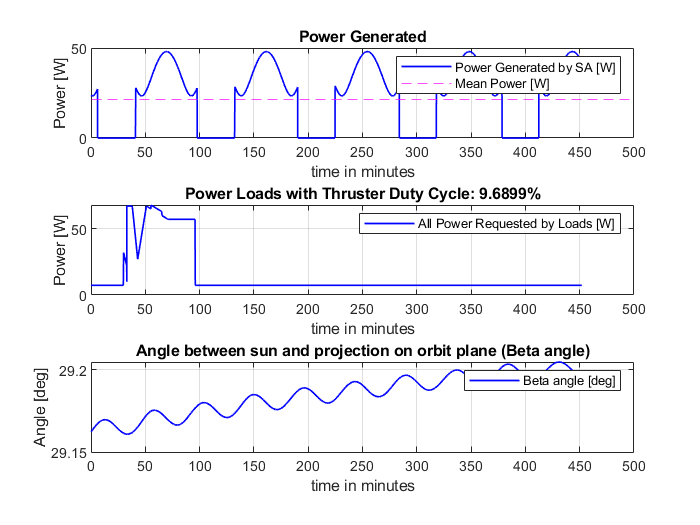

close all
time=timesec/60;  %to plot in minutes
mean_power_collected=mean(Pcollected);
figure(7)
set(gcf,'color','w');
    subplot(3,1,1)
        plot(time,Pcollected,'b','LineWidth',1)
        hold on;
        yline(mean_power_collected,'m--')
        legend('Power Generated by SA [W]','Mean Power [W]')
        title('Power Generated')
        ylabel('Power [W]')
        xlabel('time in minutes')
        grid on
    subplot(3,1,2)
        plot(time,Ploads,'b','LineWidth',1)
        hold on;
        legend('All Power Requested by Loads [W]')
        if EN_Thr==1
            title(['Power Loads with Thruster Duty Cycle: ',num2str(Duty_cycle),'%'])
        else
            title(['Power Loads'])
        end
        ylabel('Power [W]')
        xlabel('time in minutes')
        %ylim([0,22])
        grid on
    subplot(3,1,3)
        plot(time,beta,'b','LineWidth',1)
        hold on;
        legend('Beta angle [deg]')
        title('Angle between sun and projection on orbit plane (Beta angle)')
        ylabel('Angle [deg]')
        xlabel('time in minutes')
        grid on

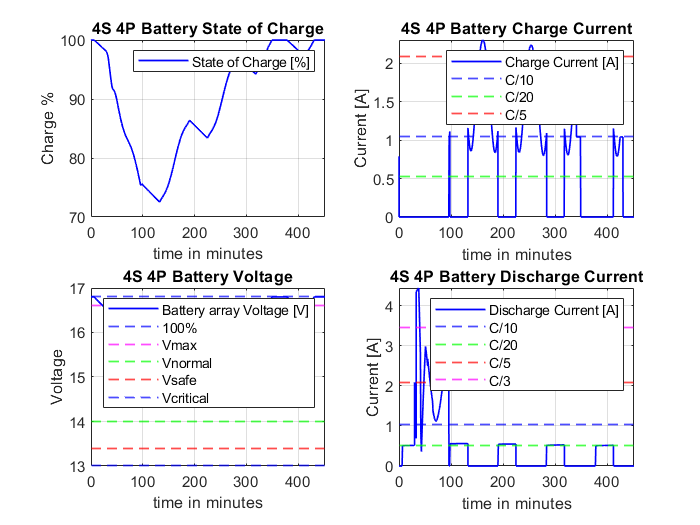


figure(8)
set(gcf,'color','w');
    subplot(2,2,1)
        plot(time,SOC,'b','LineWidth',1)
        hold on;
        legend('State of Charge [%]')
        title('4S 4P Battery State of Charge')
        ylabel('Charge %')
        xlabel('time in minutes')
        grid on
subplot(2,2,3)
        plot(time,Vbat,'b','LineWidth',1)
        hold on;
        yline(16.8, 'b--', 'LineWidth', 1);
        yline(16.6, 'm--', 'LineWidth', 1);
        yline(14.0, 'g--', 'LineWidth', 1);
        yline(13.4, 'r--', 'LineWidth', 1);
        yline(13.0, 'b--', 'LineWidth', 1);
        legend('Battery array Voltage [V]','100%','Vmax','Vnormal','Vsafe','Vcritical')
        title('4S 4P Battery Voltage')
        ylabel('Voltage')
        xlabel('time in minutes')
        grid on
subplot(2,2,2)
        plot(time,ibc,'b','LineWidth',1)
        hold on;
        yline(1.04, 'b--', 'LineWidth', 1);
        yline(0.52, 'g--', 'LineWidth', 1);
        yline(2.08, 'r--', 'LineWidth', 1);
        legend('Charge Current [A]','C/10','C/20','C/5')
        title('4S 4P Battery Charge Current')
        ylabel('Current [A]')
        xlabel('time in minutes')
        grid on
subplot(2,2,4)
        plot(time,ibd,'b','LineWidth',1)
        yline(1.04, 'b--', 'LineWidth', 1);
        yline(0.52, 'g--', 'LineWidth', 1);
        yline(2.08, 'r--', 'LineWidth', 1);
        yline(3.46, 'm--', 'LineWidth', 1);
        hold on;
        legend('Discharge Current [A]','C/10','C/20','C/5','C/3')
        title('4S 4P Battery Discharge Current')
        ylabel('Current [A]')
        xlabel('time in minutes')
        grid on